% Input the sequence
xn = input('Input sequence: ');
N = input('Enter the number of points: ');

Xk = calcdft(xn, N);

Transformation matrix for DFT
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.7071 - 0.7071i   0.0000 - 1.0000i  -0.7071 - 0.7071i  -1.0000 - 0.0000i  -0.7071 + 0.7071i  -0.0000 + 1.0000i   0.7071 + 0.7071i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -0.7071 - 0.7071i  -0.0000 + 1.0000i   0.7071 - 0.7071i  -1.0000 - 0.0000i   0.7071 + 0.7071i   0.0000 - 1.0000i  -0.7071 + 0.7071i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.7071 + 0.7071i   0.0000 - 1.0000i   0.7071 + 0.7071i  -1.0000 - 0.0000i   0.7071 - 0.7071i  -0.0000 + 1.0000i  -0.7071 - 0.7071i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.


% Display original signal
disp('Original Signal VU21EECE010037:');

Original Signal VU21EECE010037:


disp(xn);

     1    -1     0     0     1    -1     0     0




% Display DFT result
disp('DFT X(k): ');

DFT X(k): 


disp(Xk);

   0.0000 + 0.0000i
   0.0000 - 0.0000i
   2.0000 + 2.0000i
   0.0000 - 0.0000i
   4.0000 + 0.0000i
   0.0000 - 0.0000i
   2.0000 - 2.0000i
  -0.0000 + 0.0000i



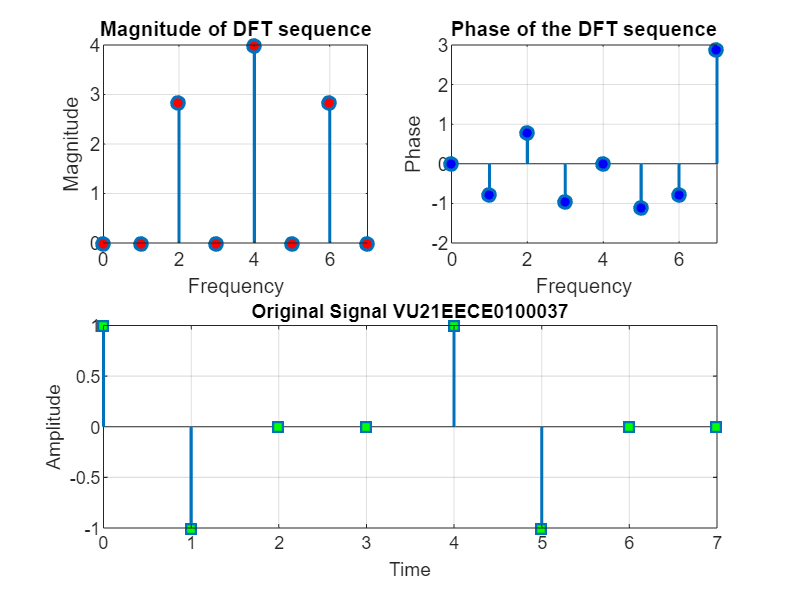


mgXk = abs(Xk);
phaseXk = angle(Xk);
k = 0:N-1;

% Plot magnitude with linewidth, color, and grid
subplot(2,2,1);
stem(k, mgXk, 'LineWidth', 1.5, 'Marker', 'o', 'MarkerFaceColor', 'r');
title('Magnitude of DFT sequence');
xlabel('Frequency');
ylabel('Magnitude');

grid on;

% Plot phase with linewidth, color, and grid
subplot(2,2,2);
stem(k, phaseXk, 'LineWidth', 1.5, 'Marker', 'o', 'MarkerFaceColor', 'b');
title('Phase of the DFT sequence');
xlabel('Frequency');
ylabel('Phase');
grid on;

% Plot original signal with linewidth, color, and grid
subplot(2,1,2);
stem(0:length(xn)-1, xn, 'LineWidth', 1.5, 'Marker', 's', 'MarkerFaceColor', 'g');
title('Original Signal VU21EECE0100037');
xlabel('Time');
ylabel('Amplitude');
grid on;

function[Xk] = calcdft(xn, N)
    L = length(xn);
    if (N < L)
        error('N must be greater than or equal to L!!');
    end
    x1 = [xn, zeros(1, N-L)];
    for k = 0:1:N-1
        for n = 0:1:N-1
            p = exp(-1i * 2 * pi * n * k / N);
            W(k+1, n+1) = p;
        end
    end
    disp('Transformation matrix for DFT');
    disp(W);
    Xk = W * (x1.');
end